% -- SPECTRAL PREPROCESSING WORKSTATION -----------------------------------
% Written by Cristian Ciobanu
%
% EDITED^2
%
% This is a workstation for preprocessing and analyzing Raman spectra.

close all;
clear;
clc;
format long;

% -- GLOBAL INTERMEDIATE PREPROCESSED SPECTRA -----------------------------
% global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn craynum 

% -- GLOBAL PREPROCESSING SETTINGS ----------------------------------------
global avgNum sgfOrder sgfWindow snipOrder snipWindow
global threshold1 threshold2 remType range NISTspectrum

% cosmic ray removal settings
threshold1 = 6;
threshold2 = 1;
range = 1;
remType = 1;

% smoothing and averaging settings
sgfOrder = 2;
sgfWindow = 11;
avgNum = 5;
snipWindow = 111;
snipOrder = 2;

% -- PREPROCESSING OPTIONS ------------------------------- 6,1,11,10,8,2,5,6,7
% 1 - Cosmic Ray Removal         2 - Savitzky-Golay Smoothing
% 3 - MSC Correction             4 - SNV Correction
% 5 - Background Removal         6 - Outlier Removal
% 7 - Normalization              8 - Shuffle Averaging
% 9 - Median                     10 - Shift correction
% 11 - NIST correction

global standardSamples std_int shifts corr_shifts crnt info

% Reading in Silicon and Polystyrene data from separate collection dates

data_path = "/Users/haydnflemming/Desktop/LLAMPE - Research Project/Data/2024-06-26/";


% Determine the number of metadata rows to skip
numMetadataRows = 21; % Adjust this based on your inspection

file_name = "Growth(10x,150mW,ND)_20000_5_2024-06-26-11.39.59.197.csv";
file_path = data_path+file_name;
growth_1 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth2(10x,150mW,ND)_20000_5_2024-06-26-11.42.28.050.csv";
file_path = strcat(data_path,file_name);
growth_2 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth3(10x,150mW,ND)_20000_5_2024-06-26-11.44.55.047.csv";
file_path = strcat(data_path,file_name);
growth_3 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth4(10x,150mW,ND)_20000_5_2024-06-26-11.47.32.150.csv";
file_path = strcat(data_path,file_name);
growth_4 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth5(10x,150mW,ND)_20000_5_2024-06-26-11.50.04.063.csv";
file_path = strcat(data_path,file_name);
growth_5 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth6(10x,150mW,ND)_20000_5_2024-06-26-11.52.27.867.csv";
file_path = strcat(data_path,file_name);
growth_6 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth7(10x,150mW,ND)_20000_2024-06-26-11.54.57.543.csv";
file_path = strcat(data_path,file_name);
growth_7 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth8(10x,150mW,ND)_20000_5_2024-06-26-11.57.28.007.csv";
file_path = strcat(data_path,file_name);
growth_8 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth9(10x,150mW,ND)_20000_5_2024-06-26-11.59.57.313.csv";
file_path = strcat(data_path,file_name);
growth_9 = csvread(file_path, numMetadataRows, 0);

file_name = "Growth10(10x,150mW,ND)_20000_5_2024-06-26-12.02.28.103.csv";
file_path = strcat(data_path,file_name);
growth_10 = csvread(file_path, numMetadataRows, 0);

file_name = "Silicon(10x,150mW,ND)_15000_10_2024-06-26-11.06.12.520.csv";
file_path = strcat(data_path,file_name);
silicon_ref = csvread(file_path, numMetadataRows, 0);

file_name = "Polystyrene(10x,150mW,ND)_3000_10_2024-06-26-11.14.05.100.csv";
file_path = strcat(data_path,file_name);
polystyrene_ref = csvread(file_path, numMetadataRows, 0);

nist1 = readmatrix('Data/NIST_0823_120523_2023-05-12-08.23.54.csv');
NISTspectrum = [growth_6(1, 1:3101) ; nist1(23:end, :)];

poly1 = readmatrix('Data/Polystyrene_1_2024-05-07-10.40.30.583.csv'); 
poly = mean(poly1(2:end,:));

Si1 = readmatrix('Data/Silicon_2_2024-05-07-10.25.23.800.csv'); 
Si = mean(Si1(2:end,:));

std_int = [poly1(1, :) ; poly ; Si];

% Configuring and plotting unprocessed data

wavenumber = growth_1(1,:);
grow4 = growth_4;
silref = silicon_ref;
polyref = polystyrene_ref;
grow1 = growth_1;
grow2 = growth_2;
grow3 = growth_3;
grow5 = growth_5;
grow6 = growth_6;
grow7 = growth_7;
grow8 = growth_8;
grow9 = growth_9;
grow10 = growth_10;

% trimming standard sample data to these WN's
t1 = 350;
t2 = 3200;
wavenumber(:, wavenumber(1, :) <= t1) = [];
wavenumber(:, wavenumber(1, :) >= t2) = [];
silref(:, silref(1, :) <= t1) = [];
silref(:, silref(1, :) >= t2) = [];
polyref(:, polyref(1, :) <= t1) = [];
polyref(:, polyref(1, :) >= t2) = [];
grow1(:, grow1(1, :) <= t1) = [];
grow1(:, grow1(1, :) >= t2) = [];
grow2(:, grow2(1, :) <= t1) = [];
grow2(:, grow2(1, :) >= t2) = [];
grow3(:, grow3(1, :) <= t1) = [];
grow3(:, grow3(1, :) >= t2) = [];
grow4(:, grow4(1, :) <= t1) = [];
grow4(:, grow4(1, :) >= t2) = [];
grow5(:, grow5(1, :) <= t1) = [];
grow5(:, grow5(1, :) >= t2) = [];
grow6(:, grow6(1, :) <= t1) = [];
grow6(:, grow6(1, :) >= t2) = [];
grow7(:, grow7(1, :) <= t1) = [];
grow7(:, grow7(1, :) >= t2) = [];
grow8(:, grow8(1, :) <= t1) = [];
grow8(:, grow8(1, :) >= t2) = [];
grow9(:, grow9(1, :) <= t1) = [];
grow9(:, grow9(1, :) >= t2) = [];
grow10(:, grow10(1, :) <= t1) = [];
grow10(:, grow10(1, :) >= t2) = [];

shifts = wavenumber;

std_int(:, std_int(1, :) <= t1) = [];
std_int(:, std_int(1, :) >= t2) = [];
std_int(1, :) = [];
standardSamples = ["Polystyrene" ; "Silicon"];

NISTspectrum(:, NISTspectrum(1, :) <= t1) = [];
NISTspectrum(:, NISTspectrum(1, :) >= t2) = [];
NISTspectrum(1, :) = [];

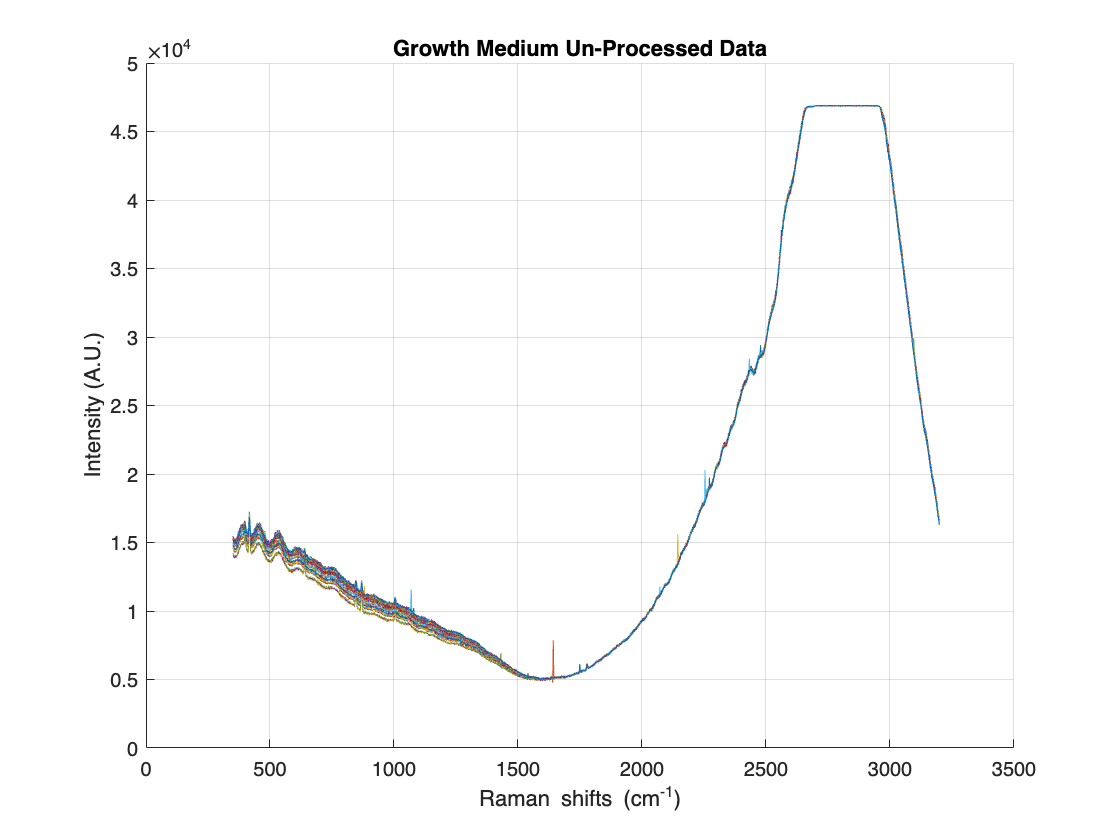

% Plotting unprocessed data

figure;
hold on;
grid on;
plot(wavenumber, grow1(2:end, :), '-');
plot(wavenumber, grow2(2:end, :), '-');
plot(wavenumber, grow3(2:end, :), '-');
plot(wavenumber, grow4(2:end, :), '-');
plot(wavenumber, grow5(2:end, :), '-');
plot(wavenumber, grow6(2:end, :), '-');
plot(wavenumber, grow7(2:end, :), '-');
plot(wavenumber, grow8(2:end, :), '-');
plot(wavenumber, grow9(2:end, :), '-');
plot(wavenumber, grow10(2:end, :), '-');
xlabel('Raman shifts (cm^{-1})')
ylabel('Intensity (A.U.)')
title('Growth Medium Un-Processed Data');
hold off;

% % Plotting time scale for each spectra
% 
% time1 = [0, 20, 40, 60, 80];
% time2 = time1+240;
% time3 = time1+420;
% time4 = time1+600;
% time5 = time1+840;
% time6 = time1+1020;
% 
% fig2 = figure;
% ax2 = axes(fig2);
% hold on;
% grid on;
% 
% plot3(wavenumber, time1(1) * ones(size(wavenumber)), grow1(2,:), 'b-');
% plot3(wavenumber, time1(2) * ones(size(wavenumber)), grow1(3,:), 'b-');
% plot3(wavenumber, time1(3) * ones(size(wavenumber)), grow1(4,:), 'b-');
% plot3(wavenumber, time1(4) * ones(size(wavenumber)), grow1(5,:), 'b-');
% plot3(wavenumber, time1(5) * ones(size(wavenumber)), grow1(6,:), 'b-');
% 
% plot3(wavenumber, time2(1) * ones(size(wavenumber)), grow2(2,:), 'r-');
% plot3(wavenumber, time2(2) * ones(size(wavenumber)), grow2(3,:), 'r-');
% plot3(wavenumber, time2(3) * ones(size(wavenumber)), grow2(4,:), 'r-');
% plot3(wavenumber, time2(4) * ones(size(wavenumber)), grow2(5,:), 'r-');
% plot3(wavenumber, time2(5) * ones(size(wavenumber)), grow2(6,:), 'r-');
% 
% plot3(wavenumber, time3(1) * ones(size(wavenumber)), grow3(2,:), 'g-');
% plot3(wavenumber, time3(2) * ones(size(wavenumber)), grow3(3,:), 'g-');
% plot3(wavenumber, time3(3) * ones(size(wavenumber)), grow3(4,:), 'g-');
% plot3(wavenumber, time3(4) * ones(size(wavenumber)), grow3(5,:), 'g-');
% plot3(wavenumber, time3(5) * ones(size(wavenumber)), grow3(6,:), 'g-');
% 
% plot3(wavenumber, time4(1) * ones(size(wavenumber)), grow4(2,:), 'm-');
% plot3(wavenumber, time4(2) * ones(size(wavenumber)), grow4(3,:), 'm-');
% plot3(wavenumber, time4(3) * ones(size(wavenumber)), grow4(4,:), 'm-');
% plot3(wavenumber, time4(4) * ones(size(wavenumber)), grow4(5,:), 'm-');
% plot3(wavenumber, time4(5) * ones(size(wavenumber)), grow4(6,:), 'm-');
% 
% plot3(wavenumber, time5(1) * ones(size(wavenumber)), grow5(2,:), 'c-');
% plot3(wavenumber, time5(2) * ones(size(wavenumber)), grow5(3,:), 'c-');
% plot3(wavenumber, time5(3) * ones(size(wavenumber)), grow5(4,:), 'c-');
% plot3(wavenumber, time5(4) * ones(size(wavenumber)), grow5(5,:), 'c-');
% plot3(wavenumber, time5(5) * ones(size(wavenumber)), grow5(6,:), 'c-');
% 
% plot3(wavenumber, time6(1) * ones(size(wavenumber)), grow6(2,:), 'k-');
% plot3(wavenumber, time6(2) * ones(size(wavenumber)), grow6(3,:), 'k-');
% plot3(wavenumber, time6(3) * ones(size(wavenumber)), grow6(4,:), 'k-');
% plot3(wavenumber, time6(4) * ones(size(wavenumber)), grow6(5,:), 'k-');
% plot3(wavenumber, time6(5) * ones(size(wavenumber)), grow6(6,:), 'k-');
% 
% xlabel(ax2, 'Raman shifts (cm^{-1})');
% ylabel(ax2, 'Time (s)');
% zlabel(ax2, 'Intensity (A.U.)');
% title('Growth Medium Un-Processed Data');
% ax2.FontSize = 18;
% view(3);

% % Preprocessing the data
% 
% pro_grow1 = apply(grow1, [6,1,10,11,8,2,5,6,7]);
% pro_grow2 = apply(grow2, [6,1,10,11,8,2,5,6,7]);
% pro_grow3 = apply(grow3, [6,1,10,11,8,2,5,6,7]);
% pro_grow4 = apply(grow4, [6,1,10,11,8,2,5,6,7]);
% pro_grow5 = apply(grow5, [6,1,10,11,8,2,5,6,7]);
% pro_grow6 = apply(grow6, [6,1,10,11,8,2,5,6,7]);
% pro_grow7 = apply(grow7, [6,1,10,11,8,2,5,6,7]);
% pro_grow8 = apply(grow8, [6,1,10,11,8,2,5,6,7]);
% pro_grow9 = apply(grow9, [6,1,10,11,8,2,5,6,7]);
% pro_grow10 = apply(grow10, [6,1,10,11,8,2,5,6,7]);
% pro_silref = apply(silref, [6,1,10,11,8,2,5,6,7]);
% pro_polyref = apply(polyref, [6,1,10,11,8,2,5,6,7]);
% 
% time = [0, 240, 420, 600, 840, 1020];
% 
% % Plotting pre-processed data
% 
% figure;
% hold on;
% grid on;
% plot(wavenumber, pro_grow1, '-b');
% plot(wavenumber, pro_grow2, '-r');
% plot(wavenumber, pro_grow3, '-g');
% plot(wavenumber, pro_grow4, '-m');
% plot(wavenumber, pro_grow5, '-c');
% plot(wavenumber, pro_grow6, '-k');
% plot(wavenumber, pro_grow7, '-k');
% plot(wavenumber, pro_grow8, '-k');
% plot(wavenumber, pro_grow9, '-k');
% plot(wavenumber, pro_grow10, '-k');
% xlabel('Raman shifts (cm^{-1})')
% ylabel('Intensity (A.U.)')
% title('Growth Medium Pre-Processed Data');
% hold off;
% figure;
% hold on;
% grid on;
% plot3(wavenumber, time(1) * ones(size(wavenumber)), pro_grow1, '-b');
% plot3(wavenumber, time(2) * ones(size(wavenumber)), pro_grow2, '-r');
% plot3(wavenumber, time(3) * ones(size(wavenumber)), pro_grow3, '-g');
% plot3(wavenumber, time(4) * ones(size(wavenumber)), pro_grow4, '-m');
% plot3(wavenumber, time(5) * ones(size(wavenumber)), pro_grow5, '-c');
% plot3(wavenumber, time(6) * ones(size(wavenumber)), pro_grow6, '-k');
% xlabel('Raman shifts (cm^{-1})');
% ylabel('Time (s)');
% zlabel('Intensity (A.U.)');
% title('Growth Medium Pre-Processed Data');
% view(3);

% % Finding peak variance (417cm^-1)
% 
% A = [pro_grow1(:,117);pro_grow2(:,117);pro_grow3(:,117);pro_grow4(:,117);pro_grow5(:,117);pro_grow6(:,117);];
% 
% av = mean(A)
% std = sqrt(var(A))
% CoV = std/av

function [all, train, test] = prepSet(data, donor, doses, ser, preprocessing)
    all = 0;
    global crnt info
    
    if donor == -1
        donor = unique(data(:,1));
    end

    if doses == -1
        doses = unique(data(:,2))';
        if ismember(999,doses)
            doses = doses(1:end-1);
        end
    end
    
    compiled_to_shuffle = cell(size(doses));
    
    for i = 1:size(donor,2)
        for j = 1:size(doses,2)
            [info, crnt] = dataPicker(data, donor(i), doses(j), ser);

            [crnt, removed] = apply(crnt, preprocessing);
            
            if ismember(8,preprocessing) || ismember(9,preprocessing)
                numRows = ones(size(crnt,1),1);
                info = [donor(i)*numRows doses(j)*numRows 999*numRows];
            else
                for k = 1:size(removed,2)
                    info(removed{k},:) = [];
                end
            end
            
            if all == 0
                all = [info crnt];
            else
                all = [all; info crnt];
            end
            
            if compiled_to_shuffle{j} == 0
                compiled_to_shuffle{j} = [info crnt];
            else
                compiled_to_shuffle{j} = [compiled_to_shuffle{j}; info crnt];
            end
        end
    end
    
    all(:,2) = all(:,2) + 1;
    [train, test] = combine(compiled_to_shuffle);
    train(:,2) = train(:,2) + 1;
    test(:,2) = test(:,2) + 1;
end

function [crnt, removed, corr_shifts] = apply(data, operations)
    global csr sgf MSC SNV bgr bge hqt nrm avg hqr mdn nistcorr NISTspectrum
    
    global avgNum sgfOrder sgfWindow snipOrder snipWindow

    global standardSamples std_int shifts corr_shifts

    global craynum range threshold1 threshold2 remType

    crnt = data;
    
    removed = {};
    
    for i = operations
        if i == 1
            % [crnt, ~, ~, craynum] = remCrays(crnt,1.5,range);
            [crnt, ~, ~, craynum] = CRremove(crnt, threshold1, threshold2, range, remType);
            csr = crnt;
        elseif i == 2
            crnt = sgolayfilt(crnt',sgfOrder,sgfWindow)';
            sgf = crnt;
        elseif i == 3
            [crnt, ~] = msc(crnt);
            MSC = crnt;
        elseif i == 4
            crnt = snv(crnt);
            SNV = crnt;
        elseif i == 5
            [crnt, bge, ~] = bgrem(crnt, snipWindow, 2, 15, snipOrder);
            bgr = crnt;
        elseif i == 6
            [crnt, hqr] = hqTest(crnt);
            removed{1,end+1} = hqr;
            hqt = crnt;
        elseif i == 7
            crnt = normr(crnt);
            nrm = crnt;
        elseif i == 8
            crnt = shuffle(crnt);
            crnt = averager(crnt, avgNum);
            avg = crnt;
        elseif i == 9
            crnt = median(crnt);                                                                    
            mdn = crnt;
       elseif i == 10
            [corr_shifts, crnt] = ramancorrect(shifts, std_int, standardSamples, crnt);
       elseif i == 11
            crnt = nistCorrect(crnt, NISTspectrum, shifts);
            nistcorr = crnt;
        end
    end
end

